# 通信原理实验2

姓名：朱天昊

学号：18922646142

邮箱：1312622783@qq.com

## 实验目标

`（1）加性高斯白噪声信道；`

`（2）多径衰落信道。`

## 实验条件

MATLAB 2016 and above, Simulink, and Communications System Toolbox .

## Prelab

## Problem 1  awgn函数

1）在正弦信号上叠加功率为-20dBW的高斯白噪声。 

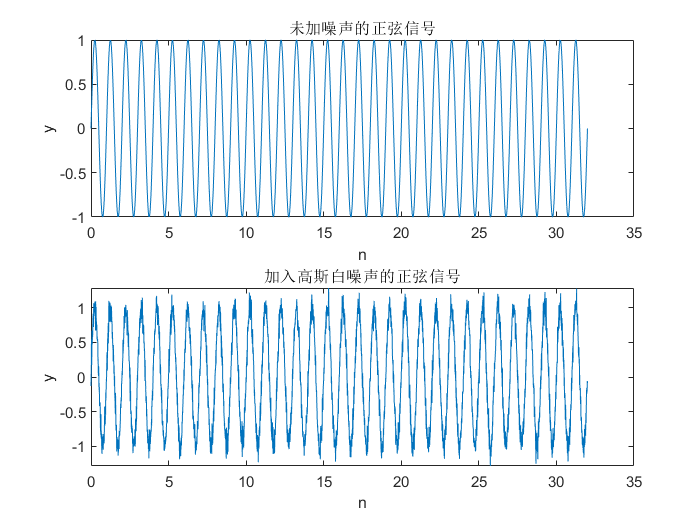

% insert your code
clear all; clc; close all;
n = 0:0.01:32;
x = sin(2*pi*n);
y = awgn(x, 20);
subplot(2,1,1);
plot(n,x); title('未加噪声的正弦信号');
xlabel('n'); ylabel('y')
subplot(2,1,2);
plot(n,y);title('加入高斯白噪声的正弦信号');
xlabel('n'); ylabel('y')

2）假设信号功率为10dBW，snr保持不变，重新求解。

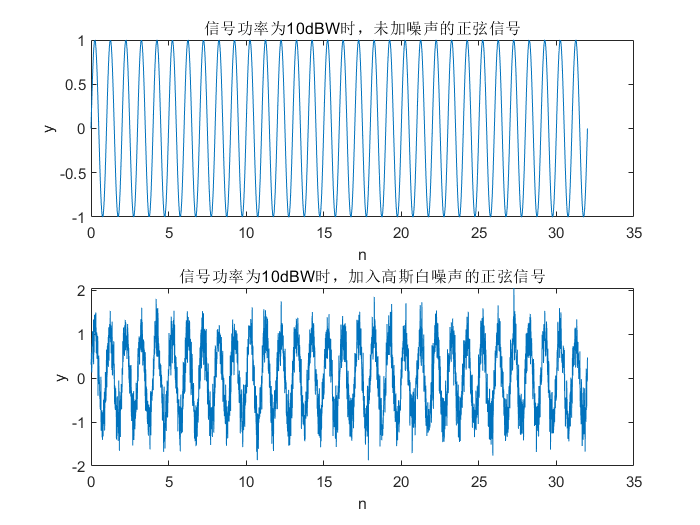

% insert your code
clear all; clc; close all;
n = 0:0.01:32;
x = sin(2*pi*n);
y = awgn(x, 20, 10);
subplot(2,1,1);
plot(n,x); title('信号功率为10dBW时，未加噪声的正弦信号');
xlabel('n'); ylabel('y')
subplot(2,1,2);
plot(n,y);title('信号功率为10dBW时，加入高斯白噪声的正弦信号');
xlabel('n'); ylabel('y')

3）根据测量的信号功率和给出的snr，重新求解。

% insert your code
clear all; clc; close all;
n = 0:0.01:32;
x = sin(2*pi*n);
y = awgn(x, 20, 'measured');
subplot(2,1,1);
plot(n,x); title('重新求解后，未加噪声的正弦信号');
xlabel('n'); ylabel('y')
subplot(2,1,2);
plot(n,y);title('重新求解后，加入高斯白噪声的正弦信号');
xlabel('n'); ylabel('y')

4）分别设state为4和5，观察产生的AWGN结果。

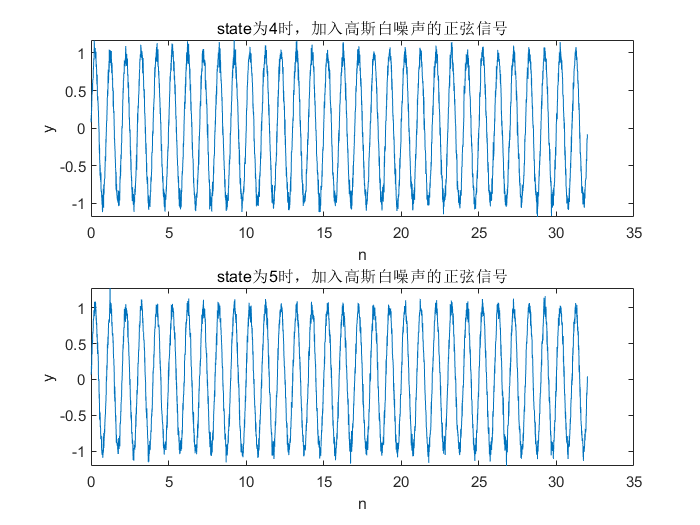

% insert your code
clear all; clc; close all;
n = 0:0.01:32;
x = sin(2*pi*n);
subplot(2,1,1);
y = awgn(x, 20, 'measured',4);
plot(n, y);  title('state为4时，加入高斯白噪声的正弦信号');
xlabel('n'); ylabel('y')
subplot(2,1,2);
y = awgn(x, 20, 'measured',5);
plot(n, y); title('state为5时，加入高斯白噪声的正弦信号');
xlabel('n'); ylabel('y')

## Problem 2  randn函数

根据测量的信号功率和给定的snr，在正弦信号上叠加高斯白噪声。

**Answer:**

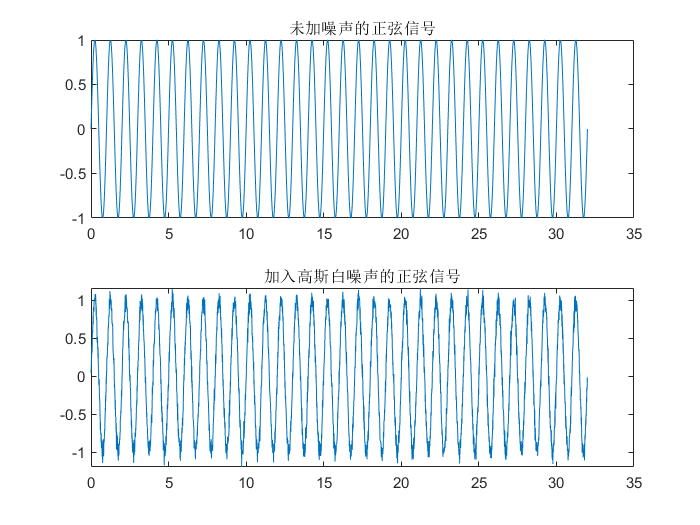

% insert your code here
clear all; clc; close all;
n = 0:0.01:32;
x = sin(2*pi*n);
y0 = randn(1, length(n));
px = norm(x).^2 / length(x);
snr = 20;
pn = px./(10.^(snr./10));
y1 = sqrt(pn) * y0;
subplot(2,1,1);
g = x + y1;
subplot(2,1,1);
plot(n,x); title('未加噪声的正弦信号');
subplot(2,1,2);
plot(n,g); title('加入高斯白噪声的正弦信号');

Note：区别对比awgn和randn函数的使用方法。

## Problem 3 衰落信道

观察多径效应和多普勒效应带来的频率选择性和时间选择性影响。

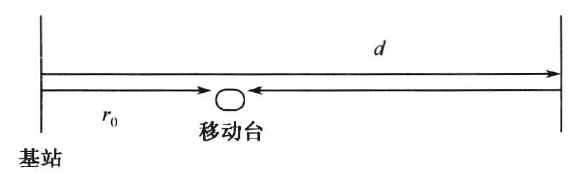

如图所示，在一条笔直高速公路上的一端安装了一个基站，在另一端有一面完全反射电磁波的镜面，基站距离反射面的距离为$d$，移动台距离基站初始距离为$r_0$。基站发射一个单音信号，频率为$f$。由于镜面的反射，移动台接收到了2径信号，其中一个是基站直接发射的信号，另一个是镜面反射过来的信号。

3.1 在$r_0$处的接收信号会有什么特点？

接收合成信号可以表示为：


$$E\left(t\right)=\frac{\cos \left\lbrack 2\pi f\left(t-\frac{r_0 }{c}\right)\right\rbrack }{r_0 }-\frac{\cos \left\lbrack 2\pi f\left(t-\frac{2d-r_0 }{c}\right)\right\rbrack }{2d-r_0 }$$


3.2 移动台向反射强运动，速度为$v$，在$r_0$处的接收信号会有什么特点？

接收合成信号可以表示为：


$$E\left(t\right)=\frac{\cos \left\lbrack 2\pi f\left(t-\frac{r_0 }{c}\right)\right\rbrack }{r_0 +\textrm{vt}}-\frac{\cos \left\lbrack 2\pi f\left(t-\frac{2d-r_0 }{c}\right)\right\rbrack }{2d-r_0 -\textrm{vt}}$$


**Answer:**

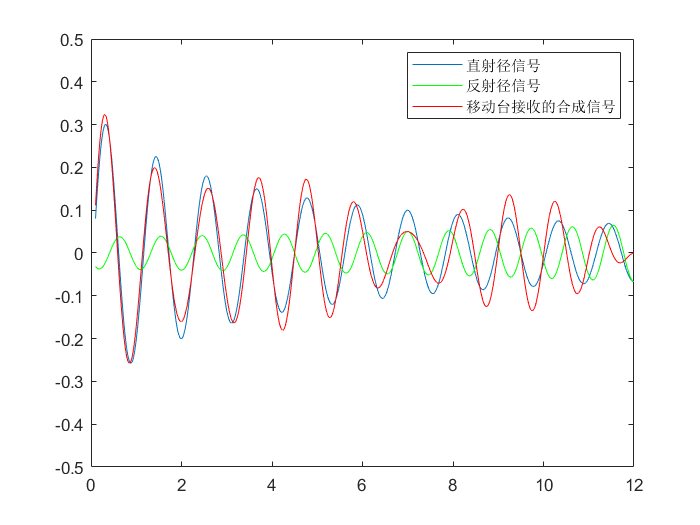

% insert your code here
f=1;		%发射信号频率
v=1;		%移动台速度，静止情况为0
c=10;      %电磁波速度，光速
r0=3;       %移动台距离基站初始距离
d=15;       %基站距离反射墙的距离
t1=0.1:0.0001:12;	%时间
E1=cos(2*pi*f*((1-v/c).*t1-r0/c))./(r0+v.*t1);          %直射径信号
E2=cos(2*pi*f*((1+v/c)*t1+(r0-2*d)/c))./(2*d-r0-v*t1);  %反射径信号
figure
plot(t1,E1,t1,E2,'-g',t1,E1-E2,'-r')           %画出直射径、反射径和总的接收信号
legend('直射径信号','反射径信号','移动台接收的合成信号')
axis([0 12 -0.5 0.5])

Note：1）改变$f$的大小，发现当$f$接近${10}^8$时，接收合成信号被增强了。因为反射径与直射径的传播时延之差为$T_d =\frac{2d-r}{c}-\frac{r}{c}$。2）多普勒扩展为反射径与折射径的多普勒之差为$f_d =\frac{v}{c}f-\left(\frac{-v}{c}f\right)=\frac{2v}{c}f$。3）多径效应->延时扩展->平坦/频选；多普勒效应->多普勒扩展->快/慢。

## Lab

## Problem 1

在AWGN信道下，我们经常遇到两个关键参数：信噪比（snr）和符号/比特能量与噪声功率谱密度之比（$\frac{E_s }{n_0 },\frac{E_b }{n_0 }$），请讨论这两个参数之间的关系，并详细说明。

**Answer：**$\frac{S}{N}$=$\frac{\frac{E_b }{T_b }}{n_0 *B}$=$\frac{E_b }{n_0 }$*$\frac{R_b }{B}$,    $E_b$=$E_s$*m,  m为传输一个符号所需要的比特数

$E_b$为每比特信息所含的能量，$T_b$为传输1比特所需的时间，$R_b$=$\frac{1}{T_b }$为比特率，B为频带宽度，n0为噪声的功率谱密度。

## Postlab

## Problem 1

利用改进的Jakes模型来产生单径的平坦型瑞利衰落信道。然后分别产生最大多普勒频移为10和20的单径瑞利衰落信道，假设信号的抽样时间间隔为1/1000，并画出信道的功率随时间的变化曲线。

**Answer：**

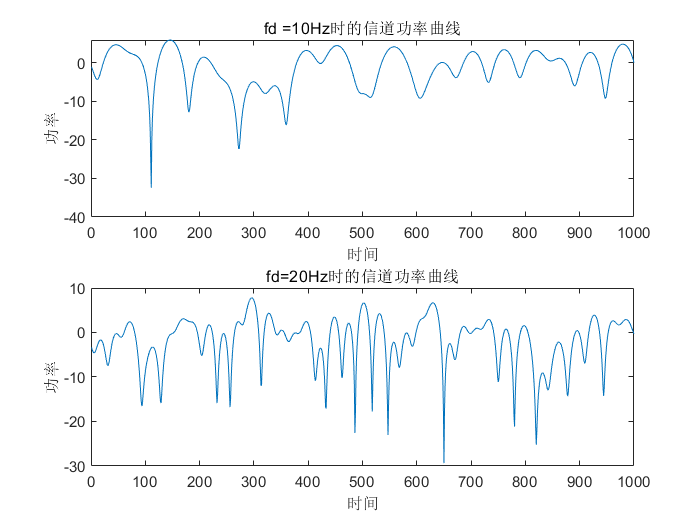

% Insert your code here
fd=10;              %多普勒频移为10
ts=1/1000;          %信道抽样时间间隔
t=0:ts:1;           %生成时间序列
h1=rayleigh_ICL(fd,t);  %产生信道数据

fd=20;              %多普勒频移为20
h2=rayleigh_ICL(fd,t);  %产生信道数据
subplot(2,1,1),plot(20*log10(abs(h1(1:1000))))
title('fd =10Hz时的信道功率曲线')
xlabel('时间');ylabel('功率')
subplot(2,1,2),plot(20*log10(abs(h2(1:1000))))
title('fd=20Hz时的信道功率曲线')
xlabel('时间');ylabel('功率')

## Problem2

产生最大多普勒频移为120的多径瑞利衰落信道，假设信号的抽样时间间隔为1/100000s，多径延迟为[0   6e-5   11e-5]，各径增益为[0  -3  -6]，所有路径的接收信号强度之和为0，画出信道的功率随时间的变化曲线。

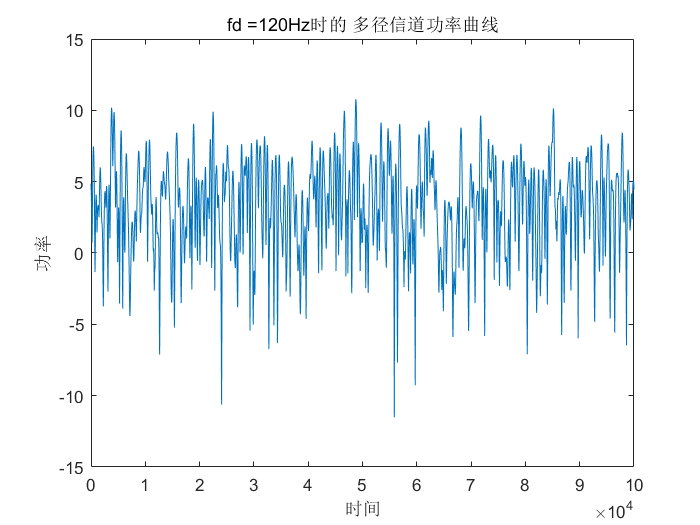

clear all;clc;close all;
fd=120;              %多普勒频移为120
ts=1/100000;          %信道抽样时间间隔
t=0:ts:1;           %生成时间序列
h1=rayleigh_ICL(fd,t);  %产生三条路径信道的数据              
h2=rayleigh_ICL(fd,t-(6e-5));  
h3=rayleigh_ICL(fd,t-(11e-5));  
Power = 20*log10(abs(h1(1:100000)) + 10^(-3/10).*abs(h2(1:100000)) + 10^(-6/10).*abs(h3(1:100000)));
plot(Power);
title('fd =120Hz时的 多径信道功率曲线')
xlabel('时间');ylabel('功率')

function [h]=rayleigh_ICL(fd,t)

%输入变量说明：
%  fd：信道的最大多普勒频移 单位Hz     
%  t :信号的抽样时间序列，抽样间隔单位s  
%  h为输出的瑞利信道函数，是一个时间函数复序列 

    %假设的入射波数目
    N=40; 

    wm=2*pi*fd;
    %每象限的入射波数目即振荡器数目
    N0=N/4;
    %信道函数的实部
    Tc=zeros(1,length(t));
    %信道函数的虚部
    Ts=zeros(1,length(t));
    %归一化功率系数
    P_nor=sqrt(1/N0);
    %区别各条路径的均匀分布随机相位
    theta=2*pi*rand(1,1)-pi;
    alfa=zeros(1,N0);
    for ii=1:N0
          %第i条入射波的入射角 
            alfa(ii)=(2*pi*ii-pi+theta)/N;
            %对每个子载波而言在(-pi,pi)之间均匀分布的随机相位
            fi_tc=2*pi*rand(1,1)-pi;
            fi_ts=2*pi*rand(1,1)-pi;
            %计算冲激响应函数
            Tc=Tc+cos(cos(alfa(ii))*wm*t+fi_tc);
            Ts=Ts+cos(sin(alfa(ii))*wm*t+fi_ts);
    end
    %乘归一化功率系数得到传输函数
   h=P_nor*(Tc+1i*Ts );
end


